# HW 3 Matlab

## HW3 q1 signal $x\left\lbrack n\right\rbrack =\alpha^n$

n = 0:1:999;
a = 0.6;
x1 = a.^n;
% calculating the sum in the space of 0-999 can be done with the sum function
res = sum(x1)

res = 2.5000

fprintf('The z-transform comes out to %2.2f.\n',res)

The z-transform comes out to 2.50.


## q2 - 1 

This would normally just be called once and you can update it using the slider to get to 8, starts off with $k=4$

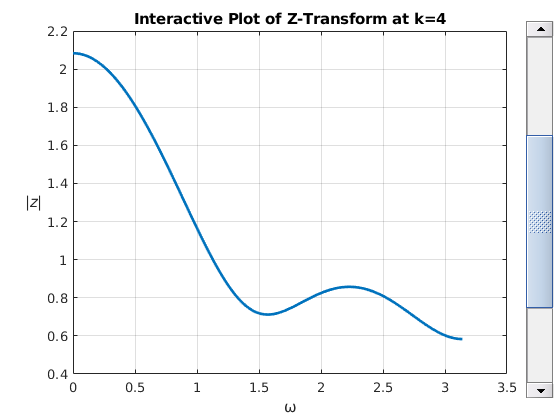

% Define the signal h[n] = 1/n
h = @(n) 1 ./ n;

% Create a figure
figure;

% Initialize k
k_init = 4;

% Precompute Z-Transform values
omega_values = 0:.01:pi;
z_values = arrayfun(@(omega) computeZTransformFunc(k_init, omega, h), omega_values);

% Plot the initial data
plot3_handle = plot(omega_values, abs(z_values), 'LineWidth', 2);
%plot3_handle = plot(omega_values, abs(z_values), 'LineWidth', 2);
xlabel('ω');
ylabel('\it|z|',Rotation=0);
title(sprintf('Interactive Plot of Z-Transform at k=%d',k_init));
grid on;

% Create a slider for k with integer steps
% Create a slider for k with integer steps and custom position
slider_handle = uicontrol('Style', 'slider', 'Min', 1, 'Max', 8, 'Value', k_init, 'SliderStep', [1, 1], 'Units', 'normalized', 'Position', ...
                          [.94, .05, 0.05, 0.9], 'Callback', @(src, event) updatePlot(src, event, plot3_handle, omega_values, h));

## q2 - 2

This would normally just be called once and you can update it using the slider to get to 8, but this will not appear on the html so I included everything again and changed the starting val to $k=8$

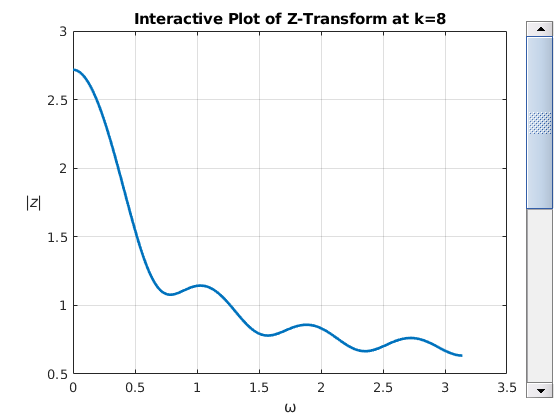

% Define the signal h[n] = 1/n
h = @(n) 1 ./ n;

% Create a figure
figure;

% Initialize k
k_init = 8;

% Precompute Z-Transform values
omega_values = 0:.01:pi;
z_values = arrayfun(@(omega) computeZTransformFunc(k_init, omega, h), omega_values);

% Plot the initial data
plot3_handle = plot(omega_values, abs(z_values), 'LineWidth', 2);
%plot3_handle = plot(omega_values, abs(z_values), 'LineWidth', 2);
xlabel('ω');
ylabel('\it|z|',Rotation=0);
title(sprintf('Interactive Plot of Z-Transform at k=%d',k_init));
grid on;

% Create a slider for k with integer steps
% Create a slider for k with integer steps and custom position
slider_handle = uicontrol('Style', 'slider', 'Min', 1, 'Max', 8, 'Value', k_init, 'SliderStep', [1, 1], 'Units', 'normalized', 'Position', ...
                          [.94, .05, 0.05, 0.9], 'Callback', @(src, event) updatePlot(src, event, plot3_handle, omega_values, h));

## prob 3 - evaluating the function in q1 with visual representation

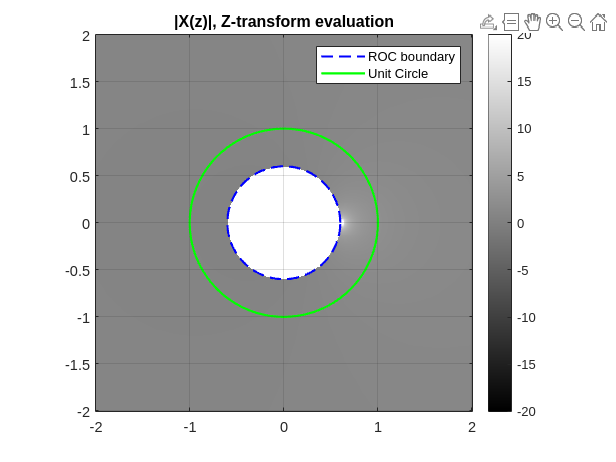


a = 0.6;
n = 0:999;
x_n = a .^ n;

minimum = -2;
maximum = 2;
step_size = .01;
n_step = (maximum - minimum)/step_size + 1;
f = linspace(minimum,maximum,(n_step));
[x,y] = meshgrid(f,f);
z = x + 1i*y;
X = arrayfun(@(zval) sum(x_n .* (zval .^ -n)), z);
X(isnan(X(:))) = Inf;


% Plot the magnitude of the Z-Transform
zvals = linspace(-2, 2, n_step);
imagesc(zvals, zvals, abs(X));
axis xy; axis square; grid on;
title('|X(z)|, Z-transform evaluation');
%colormap('jet'); % jet looks much cooler
colormap('gray');
colorbar;
clim([-20 20]);

% Hold the current plot
hold on;

leg = {'ROC boundary','Unit Circle'};
% Plot the ROC boundary at |z| = a
theta = linspace(0, 2*pi, 360);
x_roc = a * cos(theta);
y_roc = a * sin(theta);
plot(x_roc, y_roc, 'b--', 'LineWidth', 1.5);

% Plot the unit circle |z| = 1
x_unit = cos(theta);
y_unit = sin(theta);
plot(x_unit, y_unit, 'g', 'LineWidth', 1.5);
legend(leg)
% Release the hold
hold off;

## prob 4 - making the function negative

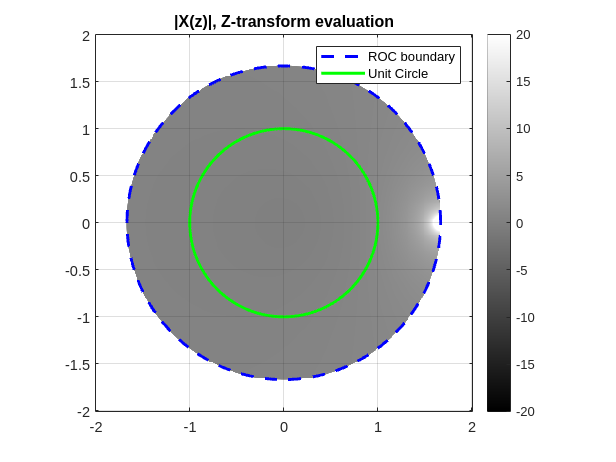

figure
a = 0.6;
n = -999:-1;
x_n = -a.^(-n);
minimum = -2;
maximum = 2;
step_size = .01;
n_step = (maximum - minimum)/step_size + 1;
f = linspace(minimum,maximum,n_step);
[x,y] = meshgrid(f,f);
z = x + 1i*y;

% create function to hold the expression
X = arrayfun(@(zval) sum(x_n .* (zval .^ -n)), z);
X(isnan(X(:))) = Inf;
zvals = linspace(-2, 2, n_step);
imagesc(zvals, zvals, abs(X));
axis xy; axis square; grid on;
title('|X(z)|, Z-transform evaluation');
%colormap('jet'); % jet looks much cooler
colormap('gray');
colorbar;
clim([-20 20]);

hold on
leg = {'ROC boundary','Unit Circle'};
% Plot the ROC boundary at |z| = 1/a
theta = linspace(0, 2*pi, 360);
x_roc = a^(-1) * cos(theta);
y_roc = a^(-1) * sin(theta);
plot(x_roc, y_roc, 'b--', 'LineWidth', 2);

% Plot the unit circle |z| = 1
x_unit = cos(theta);
y_unit = sin(theta);
plot(x_unit, y_unit, 'g', 'LineWidth', 2);
legend(leg)
hold off

function updatePlot(src, ~, plot3_handle, omega_values, h)
    k = round(src.Value); % Round to the nearest integer
    src.Value = k; % Update the slider value to the rounded integer
    z_values = arrayfun(@(omega) computeZTransformFunc(k, omega, h), omega_values); % Recompute Z-Transform values
    set(plot3_handle, 'XData', omega_values, 'YData', real(z_values), 'ZData', imag(z_values)); % Update the plot
    title(sprintf('Interactive 3D Plot of Z-Transform at %d',k));
end

% Compute the Z-Transform (nested function)
function z_value = computeZTransformFunc(k, omega, h)
    h_values = arrayfun(h, 1:k); % h[n] = 1/n
    z_value = abs(sum(h_values .* exp(-1i * (1:k) * omega)));
end

